### Get generating_data

mainFolderPath = strcat('Z:\Projects\РФФИ-Норвегия\Данные\', ...
    'Экспериментальные данные в лаборатории\', ...
    'Droplet freezing facility data\Generating droplets\');

data_name = 'GENERATING_DATA.csv';

data_path = strcat(mainFolderPath,data_name);

gen_df = readtable(data_path)

gen_df = 1387×29 table
    test    crop      test_type       voltage    pressure    impulse_time      needle        nozzle      distance    calibrat_test    record_rate                                                                        comments                                                                        experiment_date       tester        video     pixel_size    old_flow_type    old_droplet_size    droplet_count    flow_type     droplet_size    sigma_droplet_size    starting_velocity    ending_velocity    fall_time    vertical_path    <s

### Get single-droplets of new Nozzle tests

single_params = struct

single_params = struct with no fields.


border_params = struct

border_params = struct with no fields.


single_params.five = gen_df(((gen_df.crop==0) & (strcmp(gen_df.flow_type,'single')))...
    & strcmp(gen_df.nozzle,'NZ11') & (gen_df.impulse_time == 5000),:);
single_params.four = gen_df(((gen_df.crop==0) & (strcmp(gen_df.flow_type,'single')))...
    & strcmp(gen_df.nozzle,'NZ11') & (gen_df.impulse_time == 4000),:)

single_params = struct with fields:
    five: [63×29 table]
    four: [47×29 table]



% Low borders with no droplets
border_params.low.five = gen_df(((gen_df.crop==0) & (strcmp(gen_df.flow_type,'no')))...
    & strcmp(gen_df.nozzle,'NZ11') & (gen_df.impulse_time == 5000),:);
border_params.low.four = gen_df(((gen_df.crop==0) & (strcmp(gen_df.flow_type,'no')))...
    & strcmp(gen_df.nozzle,'NZ11') & (gen_df.impulse_time == 4000),:);

% Up borders with multiple or jet
border_params.up.five = gen_df(((gen_df.crop==0) & ...
    (strcmp(gen_df.flow_type,'jet')) | (strcmp(gen_df.flow_type,'multi')))...
    & strcmp(gen_df.nozzle,'NZ11') & (gen_df.impulse_time == 5000),:);
border_params.up.four = gen_df(((gen_df.crop==0) & ...
    (strcmp(gen_df.flow_type,'jet')) | (strcmp(gen_df.flow_type,'multi')))...
    & strcmp(gen_df.nozzle,'NZ11') & (gen_df.impulse_time == 4000),:);

### Create universal scale of droplets

2000 um -> 50 bubble points

bubble_scale = 50/2000

bubble_scale = 0.0250

% rows - impulse type, columns - min, max
abs_ranges = zeros(2,2);
abs_ranges(1,1) = min(single_params.five.droplet_size);
abs_ranges(1,2) = max(single_params.five.droplet_size);
abs_ranges(2,1) = min(single_params.four.droplet_size);
abs_ranges(2,2) = max(single_params.four.droplet_size);
bubble_ranges = abs_ranges.*bubble_scale;

### Plot graphics

clf
plot_table = single_params.five

plot_table = 63×29 table
    test    crop      test_type       voltage    pressure    impulse_time     needle       nozzle     distance    calibrat_test    record_rate         comments          experiment_date      tester       video     pixel_size    old_flow_type    old_droplet_size    droplet_count    flow_type     droplet_size    sigma_droplet_size    starting_velocity    ending_velocity    fall_time    vertical_path    max_horizontal_deviation    impulse_count    crop_count
    ____

low_border_table = border_params.low.five

low_border_table = 49×29 table
    test    crop      test_type       voltage    pressure    impulse_time     needle       nozzle     distance    calibrat_test    record_rate                               comments                                experiment_date      tester       video     pixel_size    old_flow_type    old_droplet_size    droplet_count    flow_type    droplet_size    sigma_droplet_size    starting_velocity    ending_velocity    fall_time    vertical_path    max_horizontal_deviation    impulse_count    <s

up_border_table = border_params.up.five

up_border_table = 105×29 table
    test    crop      test_type       voltage    pressure    impulse_time     needle       nozzle     distance    calibrat_test    record_rate                                   comments                                   experiment_date      tester       video     pixel_size    old_flow_type    old_droplet_size    droplet_count    flow_type    droplet_size    sigma_droplet_size    starting_velocity    ending_velocity    fall_time    vertical_path    max_horizontal_deviation    impulse_count


bubblechart(plot_table.voltage,plot_table.pressure,...
    plot_table.droplet_size, plot_table.starting_velocity)
hold on
plot(plot_table.voltage,plot_table.pressure,...
    '.r')
% borders
hold on
plot(low_border_table.voltage,low_border_table.pressure,...
    'Xr')
hold on
plot(up_border_table.voltage,up_border_table.pressure,...
    '|black')
grid on
grid minor
xlabel('voltage, V')
xlim([100,ceil(max(plot_table.voltage)/5)*5])
xticks(100:5:ceil(max(plot_table.voltage)/5)*5);

ylabel('pressure, mbar')
ylim([0,ceil(max(plot_table.pressure)/500)*500])
yticks(0:500:ceil(max(plot_table.pressure)/500)*500);
bubblesize(bubble_ranges(1,:))
bubblelegend('Droplet size, um','Location','eastoutside')
h = colorbar

h =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.1184 0.1778]
    FontSize: 9
    Position: [0.8510 0.1143 0.0381 0.8114]
       Units: 'normalized'

  Show all properties


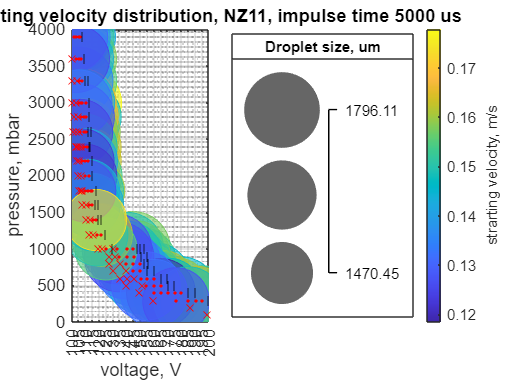

ylabel(h,'strarting velocity, m/s')
title('Droplet size and starting velocity distribution, NZ11, impulse time 5000 us')

clf
plot_table = single_params.four

plot_table = 47×29 table
    test    crop      test_type       voltage    pressure    impulse_time     needle       nozzle     distance    calibrat_test    record_rate         comments          experiment_date      tester       video     pixel_size    old_flow_type    old_droplet_size    droplet_count    flow_type     droplet_size    sigma_droplet_size    starting_velocity    ending_velocity    fall_time    vertical_path    max_horizontal_deviation    impulse_count    crop_count
    ____

low_border_table = border_params.low.four

low_border_table = 32×29 table
    test    crop      test_type       voltage    pressure    impulse_time     needle       nozzle     distance    calibrat_test    record_rate               comments                experiment_date      tester       video     pixel_size    old_flow_type    old_droplet_size    droplet_count    flow_type    droplet_size    sigma_droplet_size    starting_velocity    ending_velocity    fall_time    vertical_path    max_horizontal_deviation    impulse_count    crop_count
    <s

up_border_table = border_params.up.four

up_border_table = 35×29 table
    test    crop      test_type       voltage    pressure    impulse_time     needle       nozzle     distance    calibrat_test    record_rate              comments               experiment_date      tester       video     pixel_size    old_flow_type    old_droplet_size    droplet_count    flow_type    droplet_size    sigma_droplet_size    starting_velocity    ending_velocity    fall_time    vertical_path    max_horizontal_deviation    impulse_count    crop_count
    


bubblechart(plot_table.voltage,plot_table.pressure,...
    plot_table.droplet_size, plot_table.starting_velocity)
hold on
plot(plot_table.voltage,plot_table.pressure,...
    '.r')
% borders
hold on
plot(low_border_table.voltage,low_border_table.pressure,...
    'Xr')
hold on
plot(up_border_table.voltage,up_border_table.pressure,...
    '|black')
grid on
grid minor
xlabel('voltage, V')
xlim([100,ceil(max(plot_table.voltage)/5)*5])
xticks(100:5:ceil(max(plot_table.voltage)/5)*5);

ylabel('pressure, mbar')
ylim([0,ceil(max(plot_table.pressure)/500)*500])
yticks(0:500:ceil(max(plot_table.pressure)/500)*500);
bubblesize(bubble_ranges(2,:))
bubblelegend('Droplet size, um','Location','eastoutside')
h = colorbar

h =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.1271 0.2029]
    FontSize: 9
    Position: [0.8530 0.1143 0.0381 0.8114]
       Units: 'normalized'

  Show all properties


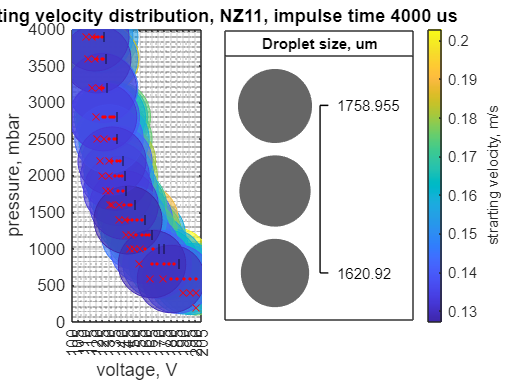

ylabel(h,'strarting velocity, m/s')
title('Droplet size and starting velocity distribution, NZ11, impulse time 4000 us') 